# Construct and Train a Function Fitting Network

Load the training data.

[x,t] = simplefit_dataset;
% The 1-by-94 matrix |x| contains the input values and the 1-by-94 matrix |t|
% contains the associated target output values.

## 用默认参数构建网络

Construct a function fitting neural network with one hidden layer of size 10.

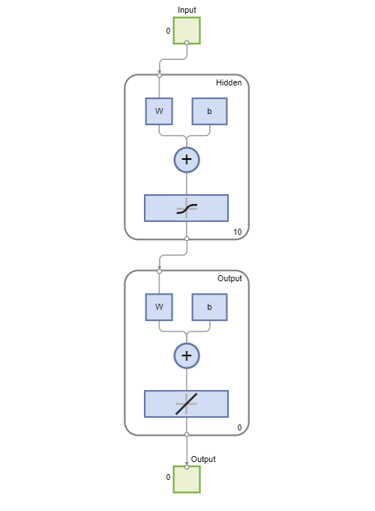

net = fitnet(10);
% View the network.
view(net)

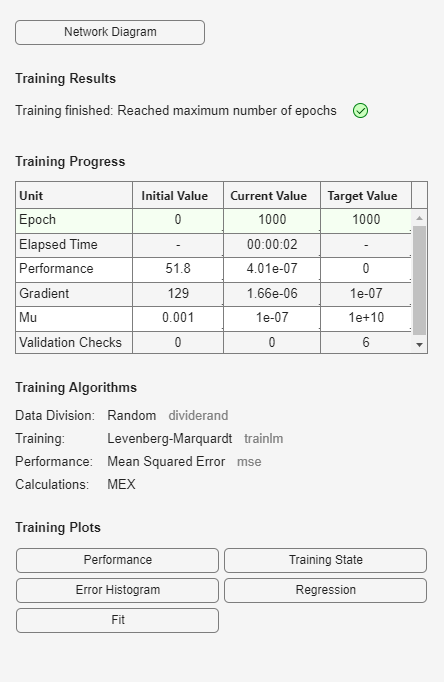

% The sizes of the input and output are zero. The software adjusts
% the sizes of these during training according to the training data.
% Train the network |net| using the training data.
net = train(net,x,t);

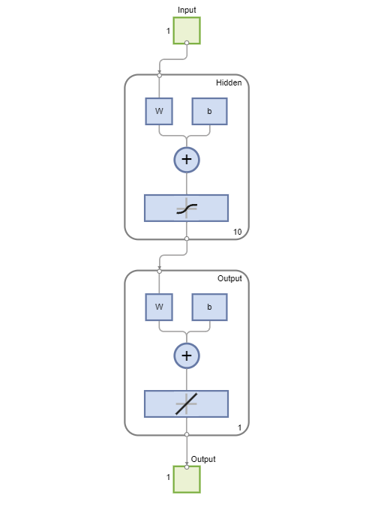

% View the trained network.
view(net)

% You can see that the sizes of the input and output are 1.
% Estimate the targets using the trained network.
y = net(x);
% Assess the performance of the trained network. The default performance function is mean squared error.
perf = perform(net,y,t)

perf = 3.2666e-05

## 换成trainbr训练函数

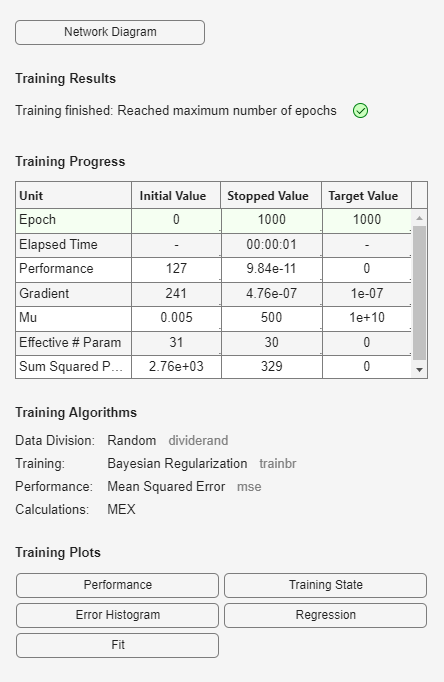

% The default training algorithm for a function fitting network is
% Levenberg-Marquardt ( |'trainlm'| ). Use the Bayesian regularization training algorithm and
% compare the performance results.
net = fitnet(10,'trainbr');
net = train(net,x,t);

y = net(x);
perf = perform(net,y,t)

perf = 2.2988e-10

% The Bayesian regularization training algorithm improves the performance of the network in terms of
% estimating the target values.